# Test cases for the half-width-at-half-max calculations

These are simple test cases for Omer's (OH) and Pablo's (PJ) functions for finding the half-width-at-half-max (HWHM) of a place field. By construction the HWHMs are 5, 1, and 4.

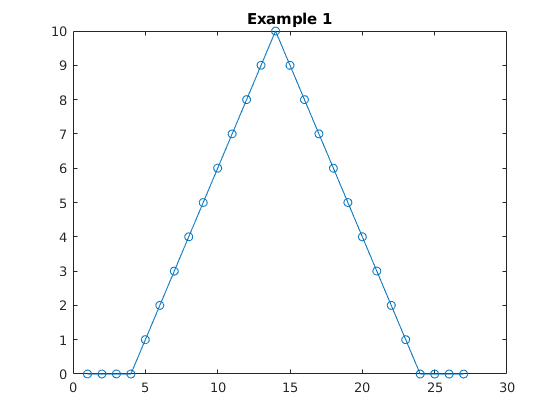

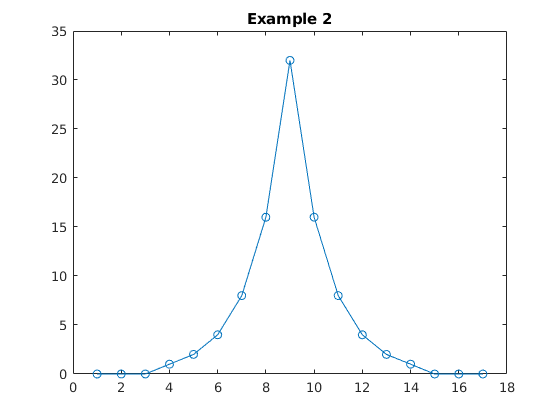

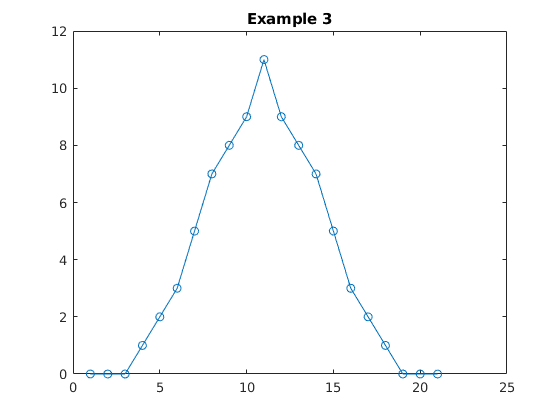

x{1} = [0 0 0 0 1 2 3 4 5 6 7 8 9 10 9 8 7 6 5 4 3 2 1 0 0 0 0]; %HWHM = 5
x{2} = [0 0 0 1 2 4 8 16 32 16 8 4 2 1 0 0 0]; %HWHM = 1
x{3} = [0 0 0 1 2 3 5 7 8 9 11 9 8 7 5 3 2 1 0 0 0]; %HWHM = 4

for i = 1:numel(x)
    figure;
    plot(x{i}, '-o');
    title(sprintf('Example %d', i));
end

## The result according to OH's code

result_oh = cellfun(@hwhm_oh, x);
for i = 1:numel(x)
    fprintf('OH reports example %d has HWHM = %d\n', i, result_oh(i));
end

OH reports example 1 has HWHM = 5
OH reports example 2 has HWHM = 1
OH reports example 3 has HWHM = 4


The results match the correct HWHMs. Before plotting, these values are converted into the full-width-at-half-max (FWHM) in centimeters by multiplying by 2 and then by the spatial bin width in cm (5.9).

## The result according to PJ's code

result_pj = cellfun(@hwhm_pj, x);

peak = 10

positPeak = 14

TopW = 2.0077

HW = 10

Slopes1090 = 1

INFR = 7.2727

OUTFR = 1.2500

peak = 32

positPeak = 9

TopW = 2.0565

HW = 2

Slopes1090 = 0.1667

INFR = 21.3333

OUTFR = 2.1429

peak = 11

positPeak = 11

TopW = 2.0621

HW = 8

Slopes1090 = 0.7500

INFR = 7.6667

OUTFR = 1

for i = 1:numel(x)
    fprintf('PJ reports example %d has HWHM = %d\n', i, result_pj(i));
end

PJ reports example 1 has HWHM = 10
PJ reports example 2 has HWHM = 2
PJ reports example 3 has HWHM = 8


The results are twice the correct HWHM. The code produced the correct FWHM, despite the output variable being named as HW (seemingly denoting half-width). If this quantity is later multiplied by 2, then this would explain why the place-field width variance values in PJ's plot are 4 times larger than those in OH's plot, but otherwise have the same statistics.

function hwhm = hwhm_oh(x)
x = x - min(x);
[mx, ix_max] = max(x);
hmx = mx/2;

pre_x = x(1:ix_max);
post_x = x(ix_max:end);

left_bound = find(pre_x <= hmx, 1, "last");
if isempty(left_bound)
    left_hw = -inf;
else
    left_hw = ix_max - left_bound;
end

right_bound = find(post_x <= hmx, 1, "first");
if isempty(right_bound)
    right_hw = -inf;
else
    right_hw = right_bound - 1;
end

hwhm = max(left_hw, right_hw);
if hwhm < 0
    assert(all(x >= hmx));
    warning('Value never dipped below half max.');
    hwhm = round(numel(x)/2);
end
end

function hwhm = hwhm_pj(x)
SmoothRF = x;
RF = [];
ResampleRate = 1;
[peak,positPeak,TopW,HW,Slopes1090,INFR,OUTFR]=slopeAndHalfWidthFinderNEW(RF,SmoothRF,ResampleRate);

hwhm = HW;
end